# 幅频相频特性曲线

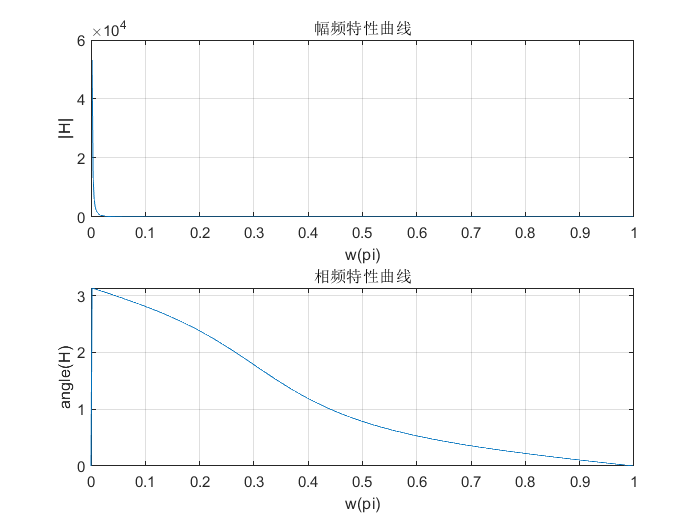

clc
clear
close all

% b=[0.0181,0.0543,0.0543,0.0181];
% a=[1.000,-1.76,1.1829,-0.2781];
b=[1,-2,3];
a=[1,-2,1];

%求系统函数
[h,w] = freqz(b,a);
%幅频函数Hf
Hf = abs(h);
%相频函数Hx
Hx = angle(h);

subplot(2,1,1);
plot(w./pi,Hf);
%加网格
grid on;
xlabel('w(pi)');
ylabel('|H|');
title('幅频特性曲线');

subplot(2,1,2);
plot(w./pi,Hx);
grid on;
xlabel('w(pi)');
ylabel('angle(H)');
title('相频特性曲线');